# DEREVERB

clc; clear; close all;

## Load Data

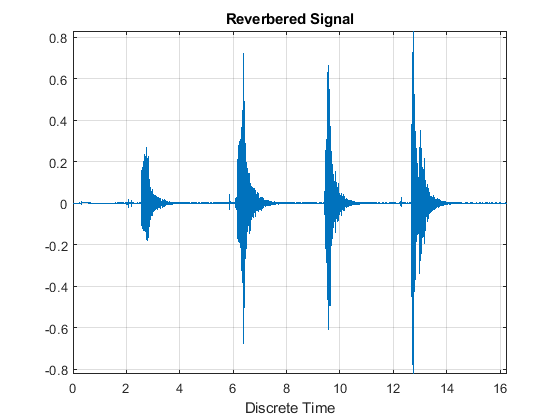

[x,Fs] = audioread("reverbered.wav");
%sound(x,Fs)
x_mono = sum(x,2);
N = length(x_mono);

Ts = 1/Fs;
time_axis = 0:Ts:(N-1)*Ts;

figure()
plot(time_axis,x_mono)
title("Reverbered Signal")
xlabel("Discrete Time")
axis tight
grid on

## CEPSTRAL ANALYSIS

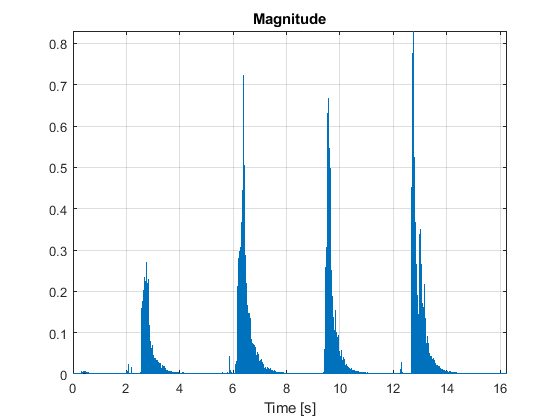

figure()
magnitude = abs(x_mono);
plot(time_axis,magnitude)
title("Magnitude")
xlabel("Time [s]")
axis tight
grid on


% SEGMENTATION by eye
segments = [[2.54896, 4.5];
            [6.15828, 7.6];
            [9.42299, 10.5];
            [12.6627, 14.0]];

limits_idx = zeros(4,2);
[~,start_idx] = min(abs(time_axis - segments(:,1)),[],2);
[~,stop_idx] = min(abs(time_axis - segments(:,2)),[],2);
limits_idx(:,1) = start_idx; limits_idx(:,2) = stop_idx;

durations = diff(limits_idx,1,2)

durations =        86041
       63580
       47496
       58975


durations = 2.^nextpow2(durations)

durations =       131072
       65536
       65536
       65536


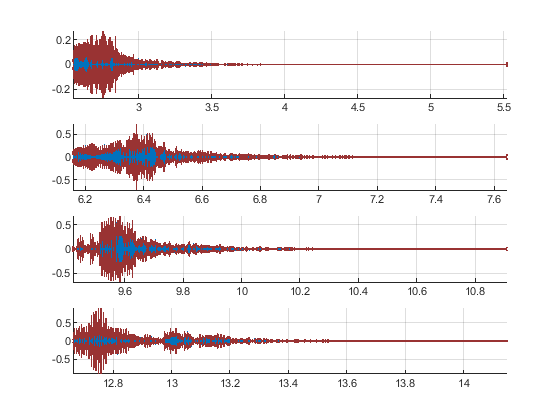

max_frame_size = max(durations);
frames = zeros(4,max_frame_size);
limits_idx(:,2) = limits_idx(:,1) + durations;

figure()
for i = 1:4
    t = time_axis(limits_idx(i,1) : limits_idx(i,2) - 1);
    frame = x_mono(limits_idx(i,1) : limits_idx(i,2) - 1);
    frames(i, 1:durations(i)) = frame;
    
    env = abs(hilbert(frame));
    plot_param = {'-','Color', [0.6 0.2 0.2],'Linewidth',1}; 
    
    subplot(4,1,i)
    hold on
    plot(t,frame)
    plot(t,[-1;1]*env',plot_param{:})
    hold off
    axis tight; grid on
    axis tight
end

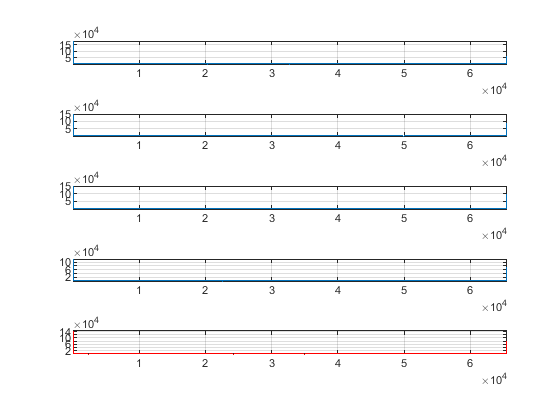

% CEPSTRUM --> Non funziona un cazzo
figure()
avg_Cepstrum = zeros(4,size(frames,2)/2 + 1);

for i = 1:4
    X = fft(frames(i,:));
    L = length(X);
    X = X(1 : L/2 + 1);
    Cepstrum = ifft(log(X));
    quefrency = 1:length(Cepstrum);
    subplot(5,1,i)
    plot(quefrency,abs(Cepstrum))
    avg_Cepstrum(i,:) = Cepstrum;
    grid on; axis tight
end

avg_Cepstrum = sum(avg_Cepstrum,1)/4;
subplot(5,1,5)
plot(quefrency, abs(avg_Cepstrum),'r')
grid on; axis tight